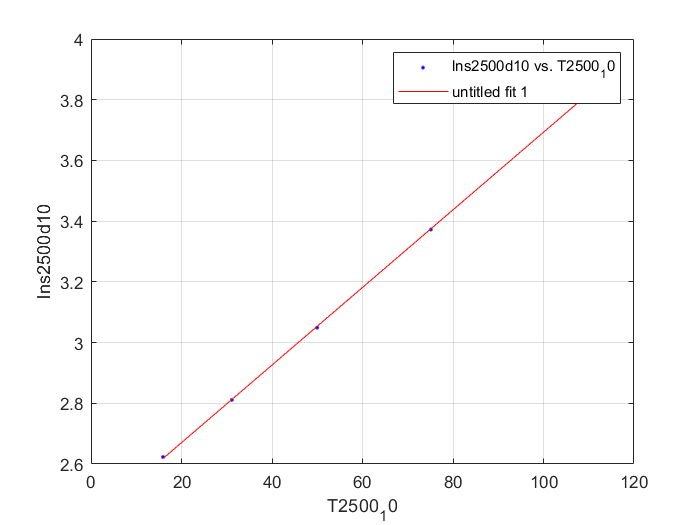

[xData, yData] = prepareCurveData( T2500_10, lns2500d10 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns2500d10 vs. T2500_10', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T2500_10
ylabel lns2500d10
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01278  (0.01259, 0.01297)
  %     p2 =       2.415  (2.402, 2.427)

%Goodness of fit:
 % SSE: 6.313e-05
  %R-square: 0.9999
 % Adjusted R-square: 0.9999
  %RMSE: 0.004587
